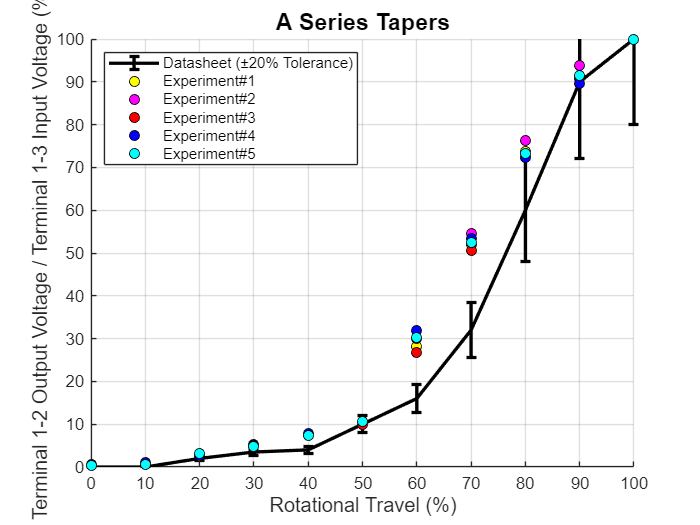



x = linspace(0, 100, 11); 
y_A1 = [0, 0, 2, 3.5, 4, 10, 16, 32, 60, 90, 100];  

y_B1 = [0.5861, 0.928, 2.344, 4.908, 7.375, 9.939, 28.06, 51.89, 73.8, 90.7, 100];
y_B2 = [0.537,0.976,2.93,5.25,7.863,10.67,29.99,54.51,76.29,93.7,100];
y_B3 = [0.488, 0.928, 2.906, 5.201, 7.668, 9.963, 26.79, 50.62, 72.63, 91.06, 100];
y_B4 = [0.415, 0.952, 2.613, 4.933, 7.741, 10.7, 31.92, 53.46, 72.26, 89.69, 100];
y_B5 = [0.464, 0.561, 3.053, 4.811, 7.399, 10.7, 30.18, 52.45, 73.24, 91.4, 100];

y_B = {y_B1, y_B2, y_B3, y_B4, y_B5};

percentage_error_yB = cell(1,5);

for i = 1:5
    abs_difference = abs(y_B{i} - y_A1);
    percentage_error_yB{i} = (abs_difference ./ y_A1) * 100;
    
    percentage_error_yB{i}(isnan(percentage_error_yB{i})) = 0;
end

percentage_error_1 = percentage_error_yB{1};
percentage_error_2 = percentage_error_yB{2};
percentage_error_3 = percentage_error_yB{3};
percentage_error_4 = percentage_error_yB{4};
percentage_error_5 = percentage_error_yB{5};



tolerance = 0.20 * y_A1;

figure;
hold on;

errorbar(x, y_A1, tolerance, '-k', 'DisplayName', 'Datasheet (±20% Tolerance)', 'LineWidth', 2);

plot(x, y_B1, 'ko', 'MarkerFaceColor', 'y', 'DisplayName', 'Experiment#1');
plot(x, y_B2, 'ko', 'MarkerFaceColor', 'm', 'DisplayName', 'Experiment#2');
plot(x, y_B3, 'ko', 'MarkerFaceColor', 'r', 'DisplayName', 'Experiment#3');
plot(x, y_B4, 'ko', 'MarkerFaceColor', 'b', 'DisplayName', 'Experiment#4');
plot(x, y_B5, 'ko', 'MarkerFaceColor', 'c', 'DisplayName', 'Experiment#5');

xlabel('Rotational Travel (%)', 'FontSize', 12);
ylabel('Terminal 1-2 Output Voltage / Terminal 1-3 Input Voltage (%)', 'FontSize', 12);
xticks(0:10:100);
xlim([0 100]);
yticks(0:10:100);
ylim([0 100]);
title('A Series Tapers', 'FontSize', 14);
legend('show', 'Location', 'northwest');
grid on;
hold off;


results_table = table(x', y_A1', y_B1', y_B2', y_B3', y_B4', y_B5', ...
    percentage_error_1', percentage_error_2', percentage_error_3', percentage_error_4', percentage_error_5', ...
    'VariableNames', {'Rotational_Travel_%', 'y_Datasheet', 'y_Experiment_1', 'y_Experiment_2', 'y_Experiment_3', 'y_Experiment_4', 'y_Experiment_5', ...
    'Percentage_Error_1', 'Percentage_Error_2', 'Percentage_Error_3', 'Percentage_Error_4', 'Percentage_Error_5'});

disp(results_table);

    Rotational_Travel_%    y_Datasheet    y_Experiment_1    y_Experiment_2    y_Experiment_3    y_Experiment_4    y_Experiment_5    Percentage_Error_1    Percentage_Error_2    Percentage_Error_3    Percentage_Error_4    Percentage_Error_5
    ___________________    ___________    ______________    ______________    ______________    ______________    ______________    __________________    __________________    __________________    __________________    __________________

              0                  0            0.5861            0.537             0.488             0.415        

% data_table = table(results_table', 'VariableNames', {'Value'}); 
data_val = rows2vars(results_table)

data_val = 12×12 table
     OriginalVariableNames      Var1     Var2     Var3      Var4      Var5     Var6      Var7      Var8      Var9      Var10     Var11
    _______________________    ______    _____    _____    ______    ______    _____    ______    ______    ______    _______    _____

    {'Rotational_Travel_%'}         0       10       20        30        40       50        60        70        80         90     100 
    {'y_Datasheet'        }         0        0        2       3.5         4       10        16        32        60         90     100 
    {'y_Experiment_1'     } 

save('data_value.mat', 'data_val');
disp(data_val);

     OriginalVariableNames      Var1     Var2     Var3      Var4      Var5     Var6      Var7      Var8      Var9      Var10     Var11
    _______________________    ______    _____    _____    ______    ______    _____    ______    ______    ______    _______    _____

    {'Rotational_Travel_%'}         0       10       20        30        40       50        60        70        80         90     100 
    {'y_Datasheet'        }         0        0        2       3.5         4       10        16        32        60         90     100 
    {'y_Experiment_1'     }    0.5861    0.928    2

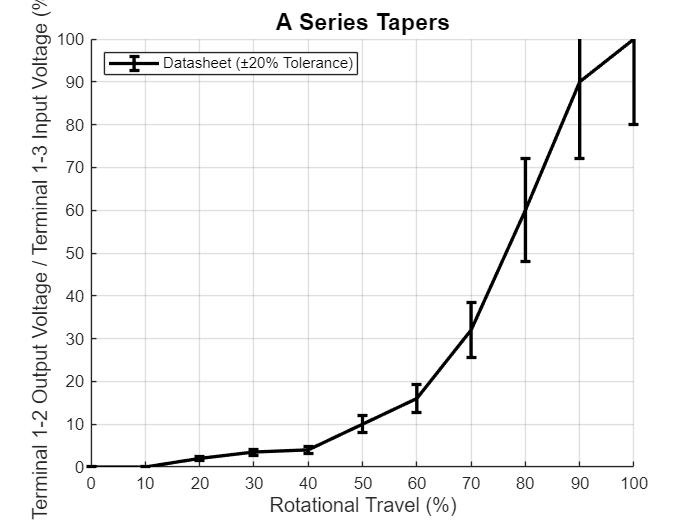


x = linspace(0, 100, 11); 
y_A1 = [0, 0, 2, 3.5, 4, 10, 16, 32, 60, 90, 100];  

tolerance = 0.20 * y_A1;

figure;
hold on;

errorbar(x, y_A1, tolerance, '-k', 'DisplayName', 'Datasheet (±20% Tolerance)', 'LineWidth', 2);


xlabel('Rotational Travel (%)', 'FontSize', 12);
ylabel('Terminal 1-2 Output Voltage / Terminal 1-3 Input Voltage (%)', 'FontSize', 12);
xticks(0:10:100);
xlim([0 100]);
yticks(0:10:100);
ylim([0 100]);
title('A Series Tapers', 'FontSize', 14);
legend('show', 'Location', 'northwest');
grid on;
hold off;

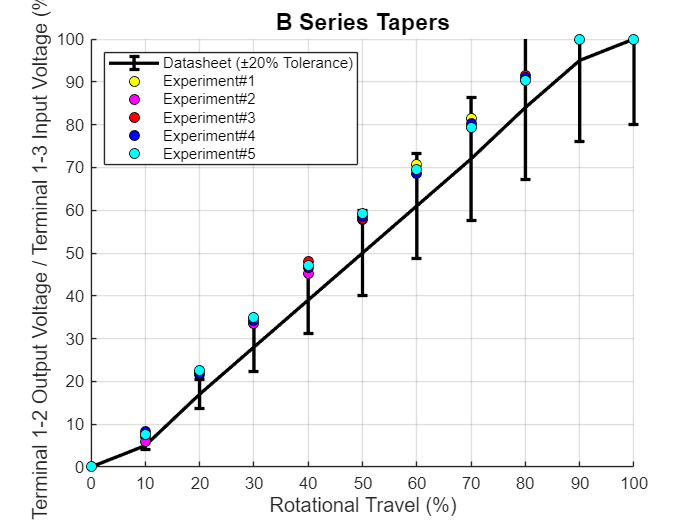


y_A1 = [0, 5, 17, 28, 39, 50, 61, 72, 84, 95, 100];  % Curve A1

y_B1 = [0,7.08,22.3,33.82,45.18,58.63,70.77,81.54,90.53,100,100];
y_B2 = [0,5.88,22.27,33.53,45.13,57.83,69.62,79.85,90.35,100,100];
y_B3 = [0, 7.91, 21.71, 34.58, 48.11, 58.07, 69.62, 80.2, 91.53,100,100];
y_B4 = [0, 8.37, 21.93, 34.31, 46.67, 58.49, 68.69, 80.17, 91.06, 100, 100];
y_B5 = [0, 7.54, 22.56, 34.99, 47.06, 59.17, 69.47, 79.34, 90.33, 100, 100];

y_B = {y_B1, y_B2, y_B3, y_B4, y_B5};

percentage_error_yB = cell(1,5);

for i = 1:5
    abs_difference = abs(y_B{i} - y_A1);
    percentage_error_yB{i} = (abs_difference ./ y_A1) * 100;
    
    percentage_error_yB{i}(isnan(percentage_error_yB{i})) = 0;
end

percentage_error_1 = percentage_error_yB{1};
percentage_error_2 = percentage_error_yB{2};
percentage_error_3 = percentage_error_yB{3};
percentage_error_4 = percentage_error_yB{4};
percentage_error_5 = percentage_error_yB{5};



tolerance = 0.20 * y_A1;

figure;
hold on;

errorbar(x, y_A1, tolerance, '-k', 'DisplayName', 'Datasheet (±20% Tolerance)', 'LineWidth', 2);

plot(x, y_B1, 'ko', 'MarkerFaceColor', 'y', 'DisplayName', 'Experiment#1');
plot(x, y_B2, 'ko', 'MarkerFaceColor', 'm', 'DisplayName', 'Experiment#2');
plot(x, y_B3, 'ko', 'MarkerFaceColor', 'r', 'DisplayName', 'Experiment#3');
plot(x, y_B4, 'ko', 'MarkerFaceColor', 'b', 'DisplayName', 'Experiment#4');
plot(x, y_B5, 'ko', 'MarkerFaceColor', 'c', 'DisplayName', 'Experiment#5');

xlabel('Rotational Travel (%)', 'FontSize', 12);
ylabel('Terminal 1-2 Output Voltage / Terminal 1-3 Input Voltage (%)', 'FontSize', 12);
xticks(0:10:100);
xlim([0 100]);
yticks(0:10:100);
ylim([0 100]);

title('B Series Tapers', 'FontSize', 14);
legend('show', 'Location', 'northwest');
grid on;
hold off;


results_table = table(x', y_A1', y_B1', y_B2', y_B3', y_B4', y_B5', ...
    percentage_error_1', percentage_error_2', percentage_error_3', percentage_error_4', percentage_error_5', ...
    'VariableNames', {'Rotational_Travel_%', 'y_Datasheet', 'y_Experiment_1', 'y_Experiment_2', 'y_Experiment_3', 'y_Experiment_4', 'y_Experiment_5', ...
    'Percentage_Error_1', 'Percentage_Error_2', 'Percentage_Error_3', 'Percentage_Error_4', 'Percentage_Error_5'});

disp(results_table);

    Rotational_Travel_%    y_Datasheet    y_Experiment_1    y_Experiment_2    y_Experiment_3    y_Experiment_4    y_Experiment_5    Percentage_Error_1    Percentage_Error_2    Percentage_Error_3    Percentage_Error_4    Percentage_Error_5
    ___________________    ___________    ______________    ______________    ______________    ______________    ______________    __________________    __________________    __________________    __________________    __________________

              0                  0                0                 0                 0                 0        

% data_table = table(results_table', 'VariableNames', {'Value'}); 
data_val = rows2vars(results_table)

data_val = 12×12 table
     OriginalVariableNames     Var1    Var2     Var3      Var4      Var5     Var6      Var7      Var8      Var9     Var10     Var11
    _______________________    ____    ____    ______    ______    ______    _____    ______    ______    ______    ______    _____

    {'Rotational_Travel_%'}     0        10        20        30        40       50        60        70        80        90     100 
    {'y_Datasheet'        }     0         5        17        28        39       50        61        72        84        95     100 
    {'y_Experiment_1'     }     0      7

save('data_value.mat', 'data_val');
disp(data_val);

     OriginalVariableNames     Var1    Var2     Var3      Var4      Var5     Var6      Var7      Var8      Var9     Var10     Var11
    _______________________    ____    ____    ______    ______    ______    _____    ______    ______    ______    ______    _____

    {'Rotational_Travel_%'}     0        10        20        30        40       50        60        70        80        90     100 
    {'y_Datasheet'        }     0         5        17        28        39       50        61        72        84        95     100 
    {'y_Experiment_1'     }     0      7.08      22.3     33.82

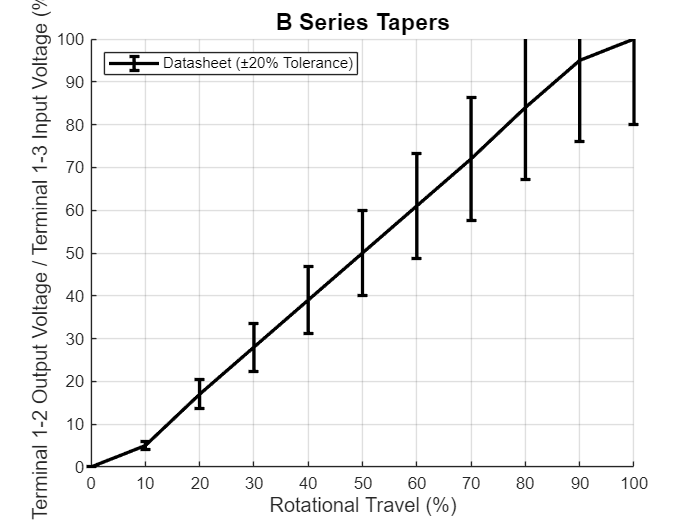

x = linspace(0, 100, 11); 
y_A1 = [0, 5, 17, 28, 39, 50, 61, 72, 84, 95, 100];  % Curve A1

tolerance = 0.20 * y_A1;

figure;
hold on;

errorbar(x, y_A1, tolerance, '-k', 'DisplayName', 'Datasheet (±20% Tolerance)', 'LineWidth', 2);


xlabel('Rotational Travel (%)', 'FontSize', 12);
ylabel('Terminal 1-2 Output Voltage / Terminal 1-3 Input Voltage (%)', 'FontSize', 12);
xticks(0:10:100);
xlim([0 100]);
yticks(0:10:100);
ylim([0 100]);
title('B Series Tapers', 'FontSize', 14);
legend('show', 'Location', 'northwest');
grid on;
hold off;

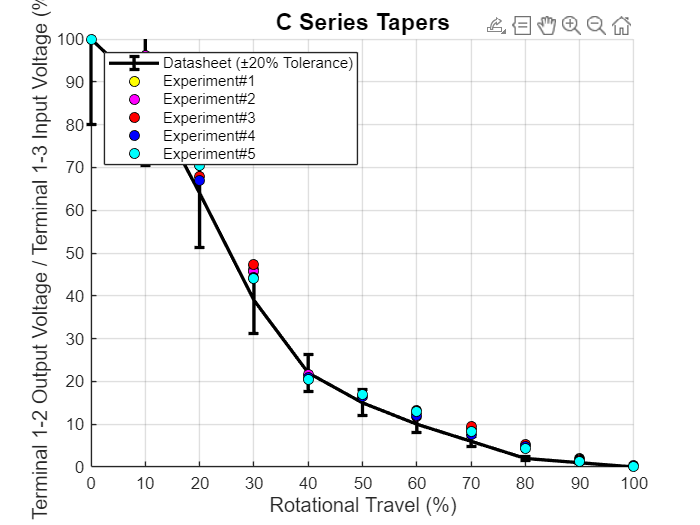


y_A1 = [100, 88, 64, 39, 22, 15, 10, 6, 2, 1, 0];

y_B1 = [100,95.34,72.31,46.25,20.73,17.02,12.48,8.69,5.27,2.05,0.12];
y_B2 = [100,96.09,70.6,45.64,21.66,16.92,11.89,8.93,5.12,1.71,0.14];
y_B3 = [100,91.45,67.99,47.33,20.9,16.73,13.19,9.37,5.2,1.44,0.09];
y_B4 = [100,95.21,66.96,44.35,20.88,16.53,12.14,7.61,4.73,1.19,0.3];
y_B5 = [100, 93.65, 70.33, 43.96, 20.44, 16.85, 12.89, 8.25, 4.29, 1.24, 0.17];

y_B = {y_B1, y_B2, y_B3, y_B4, y_B5};

percentage_error_yB = cell(1,5);

for i = 1:5
    abs_difference = abs(y_B{i} - y_A1);
    percentage_error_yB{i} = (abs_difference ./ y_A1) * 100;
    percentage_error_yB{i}(isnan(percentage_error_yB{i})) = 0;
end

percentage_error_1 = percentage_error_yB{1};
percentage_error_2 = percentage_error_yB{2};
percentage_error_3 = percentage_error_yB{3};
percentage_error_4 = percentage_error_yB{4};
percentage_error_5 = percentage_error_yB{5};



tolerance = 0.20 * y_A1;

figure;
hold on;

errorbar(x, y_A1, tolerance, '-k', 'DisplayName', 'Datasheet (±20% Tolerance)', 'LineWidth', 2);

plot(x, y_B1, 'ko', 'MarkerFaceColor', 'y', 'DisplayName', 'Experiment#1');
plot(x, y_B2, 'ko', 'MarkerFaceColor', 'm', 'DisplayName', 'Experiment#2');
plot(x, y_B3, 'ko', 'MarkerFaceColor', 'r', 'DisplayName', 'Experiment#3');
plot(x, y_B4, 'ko', 'MarkerFaceColor', 'b', 'DisplayName', 'Experiment#4');
plot(x, y_B5, 'ko', 'MarkerFaceColor', 'c', 'DisplayName', 'Experiment#5');

xlabel('Rotational Travel (%)', 'FontSize', 12);
ylabel('Terminal 1-2 Output Voltage / Terminal 1-3 Input Voltage (%)', 'FontSize', 12);
xticks(0:10:100);
xlim([0 100]);
yticks(0:10:100);
ylim([0 100]);

title('C Series Tapers', 'FontSize', 14);
legend('show', 'Location', 'northwest');
grid on;
hold off;


results_table = table(x', y_A1', y_B1', y_B2', y_B3', y_B4', y_B5', ...
    percentage_error_1', percentage_error_2', percentage_error_3', percentage_error_4', percentage_error_5', ...
    'VariableNames', {'Rotational_Travel_%', 'y_Datasheet', 'y_Experiment_1', 'y_Experiment_2', 'y_Experiment_3', 'y_Experiment_4', 'y_Experiment_5', ...
    'Percentage_Error_1', 'Percentage_Error_2', 'Percentage_Error_3', 'Percentage_Error_4', 'Percentage_Error_5'});

disp(results_table);

    Rotational_Travel_%    y_Datasheet    y_Experiment_1    y_Experiment_2    y_Experiment_3    y_Experiment_4    y_Experiment_5    Percentage_Error_1    Percentage_Error_2    Percentage_Error_3    Percentage_Error_4    Percentage_Error_5
    ___________________    ___________    ______________    ______________    ______________    ______________    ______________    __________________    __________________    __________________    __________________    __________________

              0                100              100               100               100               100        

data_val = rows2vars(results_table)

data_val = 12×12 table
     OriginalVariableNames     Var1     Var2      Var3      Var4      Var5      Var6     Var7      Var8     Var9     Var10    Var11
    _______________________    ____    ______    ______    ______    ______    ______    _____    ______    _____    _____    _____

    {'Rotational_Travel_%'}      0         10        20        30        40        50       60        70       80      90      100 
    {'y_Datasheet'        }    100         88        64        39        22        15       10         6        2       1        0 
    {'y_Experiment_1'     }    100      

save('data_value.mat', 'data_val');
disp(data_val);

     OriginalVariableNames     Var1     Var2      Var3      Var4      Var5      Var6     Var7      Var8     Var9     Var10    Var11
    _______________________    ____    ______    ______    ______    ______    ______    _____    ______    _____    _____    _____

    {'Rotational_Travel_%'}      0         10        20        30        40        50       60        70       80      90      100 
    {'y_Datasheet'        }    100         88        64        39        22        15       10         6        2       1        0 
    {'y_Experiment_1'     }    100      95.34     72.31     46.

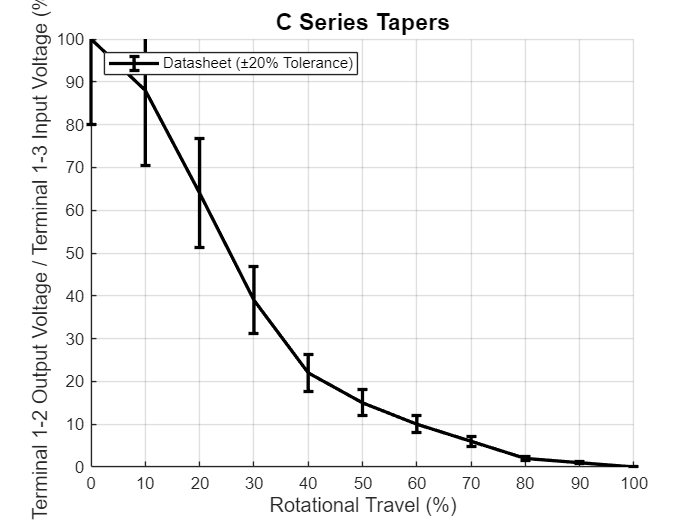

x = linspace(0, 100, 11); 
y_A1 = [100, 88, 64, 39, 22, 15, 10, 6, 2, 1, 0];

tolerance = 0.20 * y_A1;

figure;
hold on;

errorbar(x, y_A1, tolerance, '-k', 'DisplayName', 'Datasheet (±20% Tolerance)', 'LineWidth', 2);


xlabel('Rotational Travel (%)', 'FontSize', 12);
ylabel('Terminal 1-2 Output Voltage / Terminal 1-3 Input Voltage (%)', 'FontSize', 12);
xticks(0:10:100);
xlim([0 100]);
yticks(0:10:100);
ylim([0 100]);
title('C Series Tapers', 'FontSize', 14);
legend('show', 'Location', 'northwest');
grid on;
hold off;


y_A1 = [0, 1, 2, 6, 10, 15, 22, 40, 64, 90, 98];  % Curve A1

y_B1 = [0, 2.24, 6.78, 11.79, 16.53, 20.76, 32.38, 52.5, 71.28, 93.68, 100]

y_B1 =          0    2.2400    6.7800   11.7900   16.5300   20.7600   32.3800   52.5000   71.2800   93.6800  100.0000


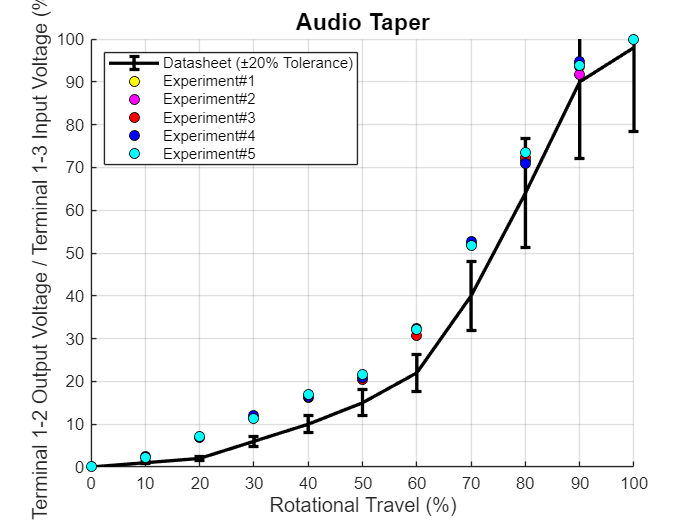

y_B2 = [0.09,2.29,6.78,11.75,16.19,21,32.31,52.21,71.67,91.8, 100];
y_B3 = [0.12,2.19,6.78,11.92,16.48,20.44,30.74,52.53,72.33,94.26, 100];

y_B4 = [0.04,2.36,7,11.94,16.56,20.85,32.38,52.67,70.94,94.68,100];
y_B5 = [0.21, 2.27, 7.08, 11.36, 16.87, 21.61, 32.01, 51.77, 73.5, 93.8, 100];

y_B = {y_B1, y_B2, y_B3, y_B4, y_B5};

percentage_error_yB = cell(1,5);

for i = 1:5
    abs_difference = abs(y_B{i} - y_A1);
    percentage_error_yB{i} = (abs_difference ./ y_A1) * 100;
    percentage_error_yB{i}(isnan(percentage_error_yB{i})) = 0;
end

percentage_error_1 = percentage_error_yB{1};
percentage_error_2 = percentage_error_yB{2};
percentage_error_3 = percentage_error_yB{3};
percentage_error_4 = percentage_error_yB{4};
percentage_error_5 = percentage_error_yB{5};



tolerance = 0.20 * y_A1;

figure;
hold on;

errorbar(x, y_A1, tolerance, '-k', 'DisplayName', 'Datasheet (±20% Tolerance)', 'LineWidth', 2);

plot(x, y_B1, 'ko', 'MarkerFaceColor', 'y', 'DisplayName', 'Experiment#1');
plot(x, y_B2, 'ko', 'MarkerFaceColor', 'm', 'DisplayName', 'Experiment#2');
plot(x, y_B3, 'ko', 'MarkerFaceColor', 'r', 'DisplayName', 'Experiment#3');
plot(x, y_B4, 'ko', 'MarkerFaceColor', 'b', 'DisplayName', 'Experiment#4');
plot(x, y_B5, 'ko', 'MarkerFaceColor', 'c', 'DisplayName', 'Experiment#5');

xlabel('Rotational Travel (%)', 'FontSize', 12);
ylabel('Terminal 1-2 Output Voltage / Terminal 1-3 Input Voltage (%)', 'FontSize', 12);
xticks(0:10:100);
xlim([0 100]);
yticks(0:10:100);
ylim([0 100]);

title('Audio Taper', 'FontSize', 14);
legend('show', 'Location', 'northwest');
grid on;
hold off;


results_table = table(x', y_A1', y_B1', y_B2', y_B3', y_B4', y_B5', ...
    percentage_error_1', percentage_error_2', percentage_error_3', percentage_error_4', percentage_error_5', ...
    'VariableNames', {'Rotational_Travel_%', 'y_Datasheet', 'y_Experiment_1', 'y_Experiment_2', 'y_Experiment_3', 'y_Experiment_4', 'y_Experiment_5', ...
    'Percentage_Error_1', 'Percentage_Error_2', 'Percentage_Error_3', 'Percentage_Error_4', 'Percentage_Error_5'});

disp(results_table);

    Rotational_Travel_%    y_Datasheet    y_Experiment_1    y_Experiment_2    y_Experiment_3    y_Experiment_4    y_Experiment_5    Percentage_Error_1    Percentage_Error_2    Percentage_Error_3    Percentage_Error_4    Percentage_Error_5
    ___________________    ___________    ______________    ______________    ______________    ______________    ______________    __________________    __________________    __________________    __________________    __________________

              0                 0                 0              0.09              0.12              0.04        

data_val = rows2vars(results_table)

data_val = 12×12 table
     OriginalVariableNames     Var1    Var2    Var3     Var4     Var5      Var6      Var7      Var8      Var9     Var10     Var11 
    _______________________    ____    ____    ____    ______    _____    ______    ______    ______    ______    ______    ______

    {'Rotational_Travel_%'}       0      10      20        30       40        50        60        70        80        90       100
    {'y_Datasheet'        }       0       1       2         6       10        15        22        40        64        90        98
    {'y_Experiment_1'     }       0    2.24 

save('data_value.mat', 'data_val');
disp(data_val);

     OriginalVariableNames     Var1    Var2    Var3     Var4     Var5      Var6      Var7      Var8      Var9     Var10     Var11 
    _______________________    ____    ____    ____    ______    _____    ______    ______    ______    ______    ______    ______

    {'Rotational_Travel_%'}       0      10      20        30       40        50        60        70        80        90       100
    {'y_Datasheet'        }       0       1       2         6       10        15        22        40        64        90        98
    {'y_Experiment_1'     }       0    2.24    6.78     11.79    16

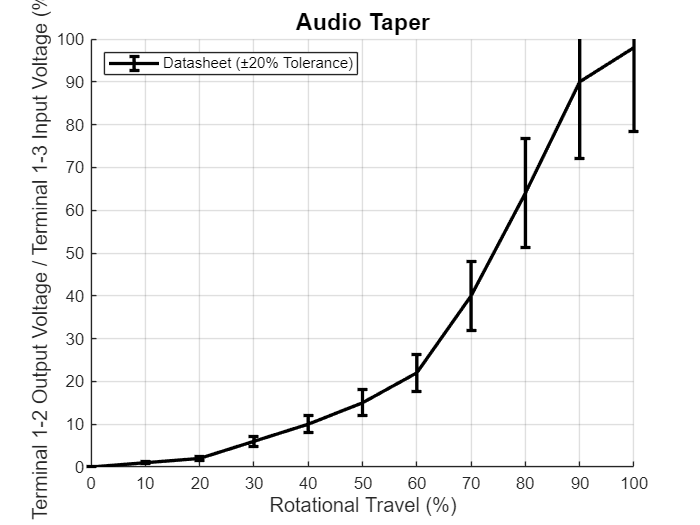

x = linspace(0, 100, 11); 
y_A1 = [0, 1, 2, 6, 10, 15, 22, 40, 64, 90, 98];  % Curve A1

tolerance = 0.20 * y_A1;

figure;
hold on;

errorbar(x, y_A1, tolerance, '-k', 'DisplayName', 'Datasheet (±20% Tolerance)', 'LineWidth', 2);


xlabel('Rotational Travel (%)', 'FontSize', 12);
ylabel('Terminal 1-2 Output Voltage / Terminal 1-3 Input Voltage (%)', 'FontSize', 12);
xticks(0:10:100);
xlim([0 100]);
yticks(0:10:100);
ylim([0 100]);
title('Audio Taper', 'FontSize', 14);
legend('show', 'Location', 'northwest');
grid on;
hold off;

x = linspace(0,100,11); % From 0 to 100% in steps of 10%

y_A1 = [0, 0, 3, 11, 30, 49, 63, 79, 93, 100, 100];  % Curve A1

y_B1 = [0, 8.13, 22.05, 33.89, 45.49, 56.21, 66.62, 76.46, 86.42, 96.48, 100]

y_B1 =          0    8.1300   22.0500   33.8900   45.4900   56.2100   66.6200   76.4600   86.4200   96.4800  100.0000


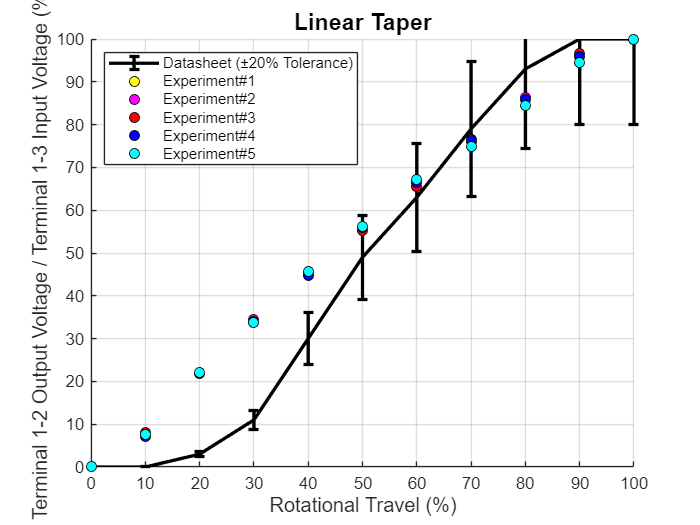

y_B2 = [0,7.47,21.88,34.36,44.96,55.51,66.54,76.31,86.4,96.34, 100];
y_B3 = [0, 8.1, 22.03, 33.89, 44.74, 55.19, 65.54, 76.09, 85.96, 96.56, 100];

y_B4 = [0, 7.22, 21.95, 33.94, 44.79, 56.07, 66.47, 76.29, 85.98, 96.02,100];
y_B5 = [0, 7.71, 22, 33.68, 45.59, 56.29, 67.16, 74.9, 84.42, 94.55, 100];

y_B = {y_B1, y_B2, y_B3, y_B4, y_B5};

percentage_error_yB = cell(1,5);

for i = 1:5
    abs_difference = abs(y_B{i} - y_A1);
    percentage_error_yB{i} = (abs_difference ./ y_A1) * 100;
    percentage_error_yB{i}(isnan(percentage_error_yB{i})) = 0;
end

percentage_error_1 = percentage_error_yB{1};
percentage_error_2 = percentage_error_yB{2};
percentage_error_3 = percentage_error_yB{3};
percentage_error_4 = percentage_error_yB{4};
percentage_error_5 = percentage_error_yB{5};



tolerance = 0.20 * y_A1;

figure;
hold on;

errorbar(x, y_A1, tolerance, '-k', 'DisplayName', 'Datasheet (±20% Tolerance)', 'LineWidth', 2);

plot(x, y_B1, 'ko', 'MarkerFaceColor', 'y', 'DisplayName', 'Experiment#1');
plot(x, y_B2, 'ko', 'MarkerFaceColor', 'm', 'DisplayName', 'Experiment#2');
plot(x, y_B3, 'ko', 'MarkerFaceColor', 'r', 'DisplayName', 'Experiment#3');
plot(x, y_B4, 'ko', 'MarkerFaceColor', 'b', 'DisplayName', 'Experiment#4');
plot(x, y_B5, 'ko', 'MarkerFaceColor', 'c', 'DisplayName', 'Experiment#5');


xlabel('Rotational Travel (%)', 'FontSize', 12);
ylabel('Terminal 1-2 Output Voltage / Terminal 1-3 Input Voltage (%)', 'FontSize', 12);
xticks(0:10:100);
xlim([0 100]);
yticks(0:10:100);
ylim([0 100]);

title('Linear Taper', 'FontSize', 14);
legend('show', 'Location', 'northwest');
grid on;
hold off;


results_table = table(x', y_A1', y_B1', y_B2', y_B3', y_B4', y_B5', ...
    percentage_error_1', percentage_error_2', percentage_error_3', percentage_error_4', percentage_error_5', ...
    'VariableNames', {'Rotational_Travel_%', 'y_Datasheet', 'y_Experiment_1', 'y_Experiment_2', 'y_Experiment_3', 'y_Experiment_4', 'y_Experiment_5', ...
    'Percentage_Error_1', 'Percentage_Error_2', 'Percentage_Error_3', 'Percentage_Error_4', 'Percentage_Error_5'});

disp(results_table);

    Rotational_Travel_%    y_Datasheet    y_Experiment_1    y_Experiment_2    y_Experiment_3    y_Experiment_4    y_Experiment_5    Percentage_Error_1    Percentage_Error_2    Percentage_Error_3    Percentage_Error_4    Percentage_Error_5
    ___________________    ___________    ______________    ______________    ______________    ______________    ______________    __________________    __________________    __________________    __________________    __________________

              0                  0                0                 0                 0                 0        

data_val = rows2vars(results_table)

data_val = 12×12 table
     OriginalVariableNames     Var1    Var2     Var3      Var4      Var5      Var6      Var7      Var8      Var9     Var10    Var11
    _______________________    ____    ____    ______    ______    ______    ______    ______    ______    ______    _____    _____

    {'Rotational_Travel_%'}     0        10        20        30        40        50        60        70        80       90     100 
    {'y_Datasheet'        }     0         0         3        11        30        49        63        79        93      100     100 
    {'y_Experiment_1'     }     0      8

save('data_value.mat', 'data_val');
disp(data_val);

     OriginalVariableNames     Var1    Var2     Var3      Var4      Var5      Var6      Var7      Var8      Var9     Var10    Var11
    _______________________    ____    ____    ______    ______    ______    ______    ______    ______    ______    _____    _____

    {'Rotational_Travel_%'}     0        10        20        30        40        50        60        70        80       90     100 
    {'y_Datasheet'        }     0         0         3        11        30        49        63        79        93      100     100 
    {'y_Experiment_1'     }     0      8.13     22.05     33.89

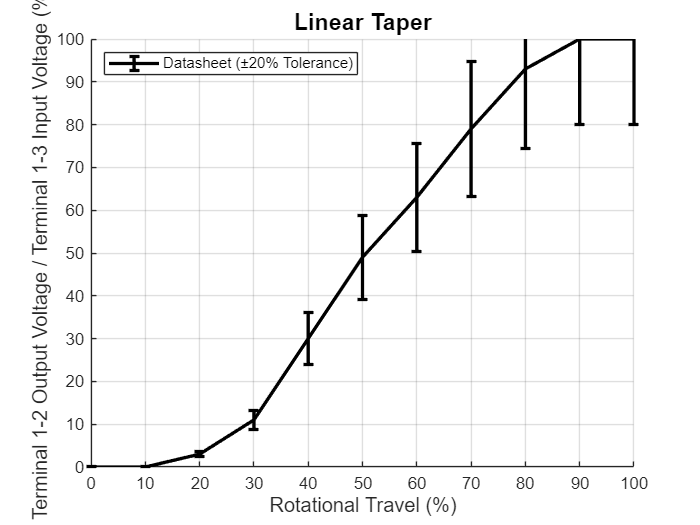

x = linspace(0, 100, 11); 
y_A1 = [0, 0, 3, 11, 30, 49, 63, 79, 93, 100, 100];  % Curve A1

tolerance = 0.20 * y_A1;

figure;
hold on;

errorbar(x, y_A1, tolerance, '-k', 'DisplayName', 'Datasheet (±20% Tolerance)', 'LineWidth', 2);


xlabel('Rotational Travel (%)', 'FontSize', 12);
ylabel('Terminal 1-2 Output Voltage / Terminal 1-3 Input Voltage (%)', 'FontSize', 12);
xticks(0:10:100);
xlim([0 100]);
yticks(0:10:100);
ylim([0 100]);
title('Linear Taper', 'FontSize', 14);
legend('show', 'Location', 'northwest');
grid on;
hold off;

% Loop through all dataset elements
rms_array = zeros(1, 10);
for i = 1:10
    % Access each dataset element
    element = data{i};  % Access the i-th dataset

    % Loop through all signals in each dataset (if there are multiple signals)
    for j = 1:element.numElements
        % Access the j-th signal in the i-th dataset
        signal = element.getElement(3);

        % Extract time and data (assuming there are 11 data points)
        time_values = signal.Values.Time;
        data_values = signal.Values.Data;



        % Ensure there are exactly 11 data points
        if length(data_values) == 11
            fprintf('Dataset %d, Signal %d:\n', i, j);
            disp('Time Values:');
            disp(time_values);  % Display time values (11 points)
            disp('Data Values:');
            rms_value = sqrt(mean(data_values.^2));
            disp(data_values);  % Display data values (11 points)
            disp('rms_value:');
            disp(rms_value);
            rms_array(i) = rms_value;
        else

            warning('Dataset %d, Signal %d does not have 11 data points.', i, j);
        end
    end
    disp('rms_all_array:');
    disp(rms_array);
    save('rms_array.mat', 'rms_array');

end

Undefined variable 'data'.

% Access the element from the data array
element = data(1);  % In MATLAB, use parentheses for indexing

% Get the specific signal element from the structure
signal = element.getElement(3);

Unrecognized method, property, or field 'getElement' for class 'timeseries'.


% Extract the data values from the signal
data_values = signal.Values.Data;

% Generate the index for the data values
index = 1:length(data_values);  % Use 1-based indexing in MATLAB
% Find valid (non-NaN) values
valid_indices = ~isnan(data_values);  % Use isnan() in MATLAB to find NaN values
valid_data = data_values(valid_indices);
valid_index = linspace(0,3.5,8)
valid_indices_list = valid_data(2:2:end);

% valid_index = 1:length(valid_data);
disp(length(valid_data));

% Plot the valid data points
figure;
plot(valid_index, valid_indices_list, 'o', 'MarkerEdgeColor', 'r', 'LineStyle', '-', 'Color', 'k');
title('Voltage Response with Distance');
xlabel('Distance (CM)');
ylabel('RMS Value (V)');
grid on;


figure;

plot(valid_index, valid_indices_list, 'o', 'MarkerEdgeColor', 'r', 'LineStyle', '-', 'Color', 'k');
hold on;  % Hold the current plot for adding the fit curve

plot(valid_index, valid_index, 'o', 'MarkerEdgeColor', 'r', 'LineStyle', '-', 'Color', 'k');


title('Valid Data Points with Exponential Best Fit');
xlabel('Distance (CM)');
ylabel('RMS Value');

legend('show');

% Add grid for better visualization
grid on;

hold off;  % Release the plot hold


%No-Shield-Firstside south
V_Q = 1.65;  
Sensitivity_25C = 60;  

element = data(1);  
% 
% signal = element.getElement(3);
% 
% data_values = signal.Values.Data;
data_values = element.Data;

index = 1:length(data_values);  
if all(isnan(data_values))
    disp('No valid data points available. Check the data source.');
else
    % Filter out NaN or replace them with zero (or another value)
    valid_data = data_values;
    valid_data(isnan(valid_data)) = 0;  % Replace NaN with 0
end
valid_indices = ~isnan(data_values);  
valid_data = data_values(valid_indices);

B = (valid_data - V_Q) / Sensitivity_25C;
disp(valid_data)

    1.6579
    1.6762
    1.7090
    1.7730
    1.9337
    2.2067
    3.2285
    3.2477




disp(B)

    0.0001
    0.0004
    0.0010
    0.0021
    0.0047
    0.0093
    0.0263
    0.0266



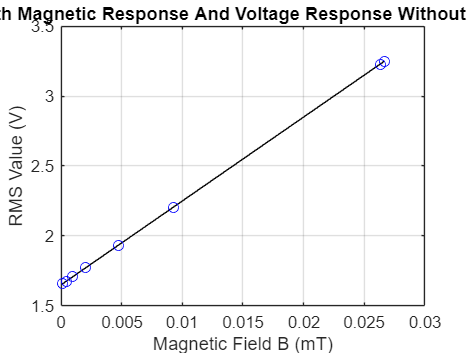


figure;
plot(B, valid_data, 'o', 'MarkerEdgeColor', 'b', 'LineStyle', '-', 'Color', 'k');
title('South Magnetic Response And Voltage Response Without Shield');
xlabel('Magnetic Field B (mT)');
ylabel('RMS Value (V)');  
grid on;


disp(numel(valid_data))

     8




valid_index = linspace(3.5,0,8)

valid_index =     3.5000    3.0000    2.5000    2.0000    1.5000    1.0000    0.5000         0


% valid_indices_list = valid_data(2:2:end);
figure;
disp(valid_data)

    1.6579
    1.6762
    1.7090
    1.7730
    1.9337
    2.2067
    3.2285
    3.2477



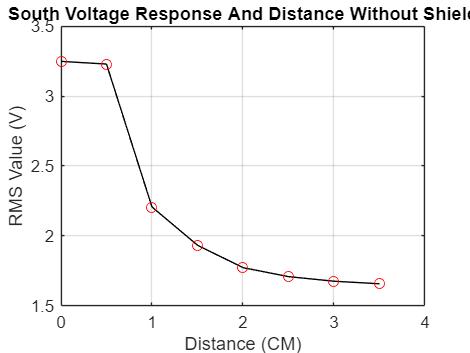


plot(valid_index, valid_data, 'o', 'MarkerEdgeColor', 'r', 'LineStyle', '-', 'Color', 'k');
title('South Voltage Response And Distance Without Shield');
xlabel('Distance (CM)');
ylabel('RMS Value (V)');
grid on;


valid_index = linspace(3.5,0,8)

valid_index =     3.5000    3.0000    2.5000    2.0000    1.5000    1.0000    0.5000         0


% valid_indices_list = valid_data(2:2:end);
figure;
disp(valid_data)

    1.6579
    1.6762
    1.7090
    1.7730
    1.9337
    2.2067
    3.2285
    3.2477



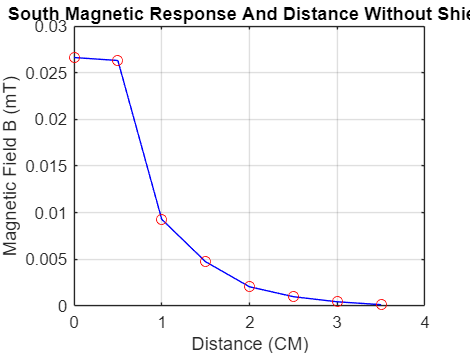


plot(valid_index, B, 'o', 'MarkerEdgeColor', 'r', 'LineStyle', '-', 'Color', 'b');
title('South Magnetic Response And Distance Without Shield');
xlabel('Distance (CM)');
ylabel('Magnetic Field B (mT)');
grid on;

%Shield-Firstside south
V_Q = 1.65;  
Sensitivity_25C = 60;  

element = data(1);  
% 
signal = element.getElement(2);
% 
% data_values = signal.Values.Data;
data_values = signal.Values.Data;

index = 1:length(data_values);  
if all(isnan(data_values))
    disp('No valid data points available. Check the data source.');
else
    
    valid_data = data_values;
    valid_data(isnan(valid_data)) = 0;  % Replace NaN with 0
end
valid_indices = ~isnan(data_values);  
valid_data = data_values(valid_indices);

B = (valid_data - V_Q) / Sensitivity_25C;
disp(valid_data)

    1.6557
    1.6687
    1.6988
    1.7534
    1.8562
    2.1779
    2.9351
    3.2371



disp(B)

    0.0001
    0.0003
    0.0008
    0.0017
    0.0034
    0.0088
    0.0214
    0.0265



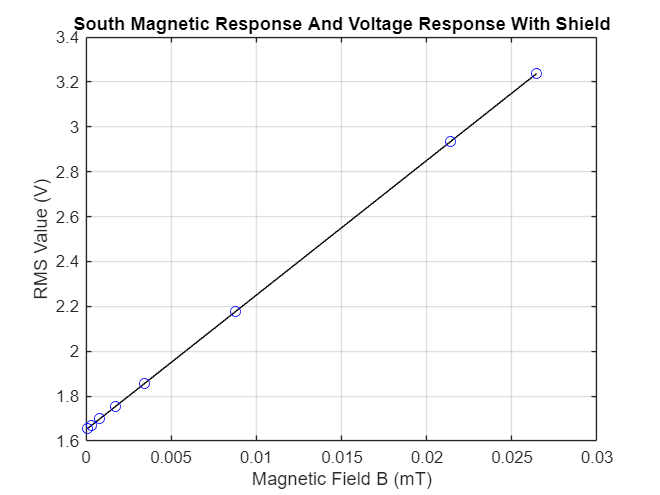


figure;
plot(B, valid_data, 'o', 'MarkerEdgeColor', 'b', 'LineStyle', '-', 'Color', 'k');
title('South Magnetic Response And Voltage Response With Shield');
xlabel('Magnetic Field B (mT)');
ylabel('RMS Value (V)');  
grid on;

disp(numel(valid_data))

     8




valid_index = linspace(3.5,0,8)

valid_index =     3.5000    3.0000    2.5000    2.0000    1.5000    1.0000    0.5000         0


% valid_indices_list = valid_data(2:2:end);
figure;
disp(valid_data)

    1.6557
    1.6687
    1.6988
    1.7534
    1.8562
    2.1779
    2.9351
    3.2371



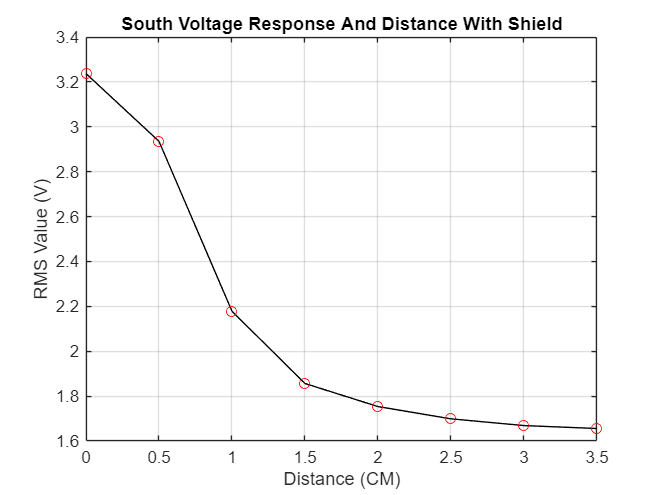


plot(valid_index, valid_data, 'o', 'MarkerEdgeColor', 'r', 'LineStyle', '-', 'Color', 'k');
title('South Voltage Response And Distance With Shield');
xlabel('Distance (CM)');
ylabel('RMS Value (V)');
grid on;

valid_index = linspace(3.5,0,8)
% valid_indices_list = valid_data(2:2:end);
figure;
disp(valid_data)

plot(valid_index, B, 'o', 'MarkerEdgeColor', 'r', 'LineStyle', '-', 'Color', 'b');
title('South Magnetic Response And Distance With Shield');
xlabel('Distance (CM)');
ylabel('Magnetic Field B (mT)');
grid on;

%No-Shield-second-side north
V_Q = 1.65;  
Sensitivity_25C = 60;  

element = data(1);  
% 
% 
% data_values = signal.Values.Data;
data_values = element.Data;

index = 1:length(data_values);  
if all(isnan(data_values))
    disp('No valid data points available. Check the data source.');
else
    
    valid_data = data_values;
    valid_data(isnan(valid_data)) = 0;  % Replace NaN with 0
end
valid_indices = ~isnan(data_values);  
valid_data = data_values(valid_indices);

B = (valid_data - V_Q) / Sensitivity_25C;
disp(valid_data)

    1.5981
    1.5831
    1.5516
    1.4899
    1.3571
    1.0964
    0.1639
    0.0449



disp(B)

   -0.0009
   -0.0011
   -0.0016
   -0.0027
   -0.0049
   -0.0092
   -0.0248
   -0.0268



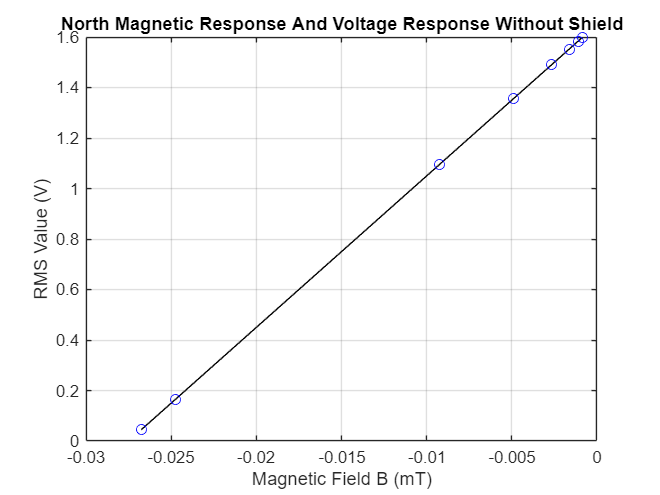

figure;
plot(B, valid_data, 'o', 'MarkerEdgeColor', 'b', 'LineStyle', '-', 'Color', 'k');
title('North Magnetic Response And Voltage Response Without Shield');
xlabel('Magnetic Field B (mT)');
ylabel('RMS Value (V)');  
grid on;

disp(numel(valid_data))

     8




valid_index = linspace(3.5,0,8)

valid_index =     3.5000    3.0000    2.5000    2.0000    1.5000    1.0000    0.5000         0


% valid_indices_list = valid_data(2:2:end);
figure;
disp(valid_data)

    1.5981
    1.5831
    1.5516
    1.4899
    1.3571
    1.0964
    0.1639
    0.0449



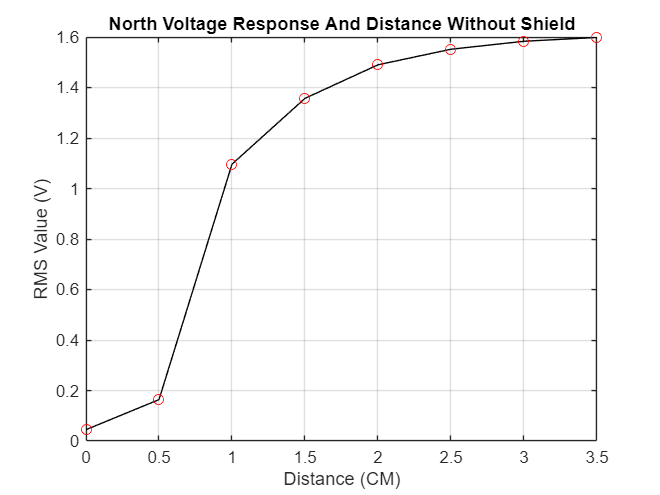

plot(valid_index, valid_data, 'o', 'MarkerEdgeColor', 'r', 'LineStyle', '-', 'Color', 'k');
title('North Voltage Response And Distance Without Shield');
xlabel('Distance (CM)');
ylabel('RMS Value (V)');
grid on;

valid_index = linspace(3.5,0,8)

valid_index =     3.5000    3.0000    2.5000    2.0000    1.5000    1.0000    0.5000         0


% valid_indices_list = valid_data(2:2:end);
figure;
disp(valid_data)

    1.5981
    1.5831
    1.5516
    1.4899
    1.3571
    1.0964
    0.1639
    0.0449



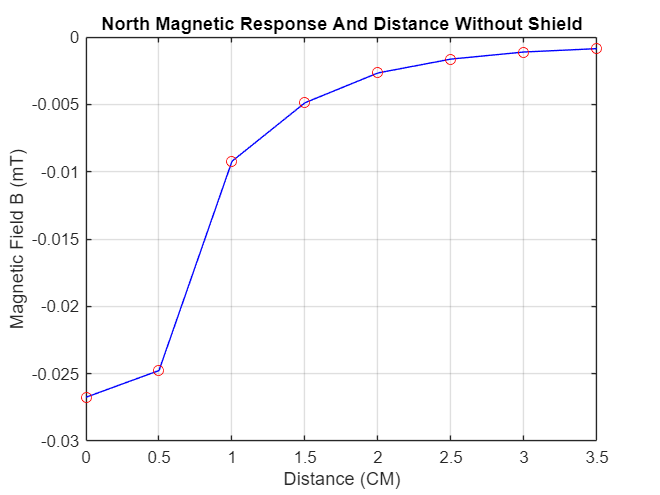


plot(valid_index, B, 'o', 'MarkerEdgeColor', 'r', 'LineStyle', '-', 'Color', 'b');
title('North Magnetic Response And Distance Without Shield');
xlabel('Distance (CM)');
ylabel('Magnetic Field B (mT)');
grid on;

%Shield-second-side north
V_Q = 1.65;  
Sensitivity_25C = 60;  

element = data(1);  
% 
% 
% data_values = signal.Values.Data;
signal = element.getElement(3);
% 
% data_values = signal.Values.Data;
data_values = signal.Values.Data;

index = 1:length(data_values);  
if all(isnan(data_values))
    disp('No valid data points available. Check the data source.');
else
    
    valid_data = data_values;
    valid_data(isnan(valid_data)) = 0;  % Replace NaN with 0
    
end
valid_indices = ~isnan(data_values);  
valid_data = data_values(valid_indices);
disp(valid_data)

    1.6021
    1.5873
    1.5608
    1.5103
    1.3919
    1.1530
    0.4272
    0.0553




B = (valid_data - V_Q) / Sensitivity_25C;
disp(valid_data)

    1.6021
    1.5873
    1.5608
    1.5103
    1.3919
    1.1530
    0.4272
    0.0553



disp(B)

   -0.0008
   -0.0010
   -0.0015
   -0.0023
   -0.0043
   -0.0083
   -0.0204
   -0.0266



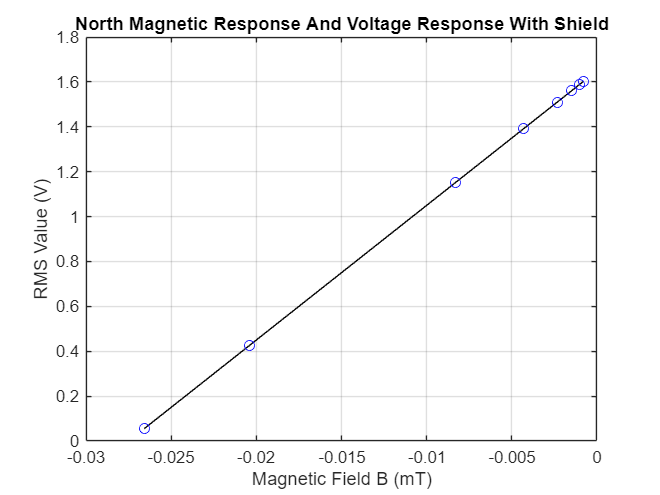

figure;
plot(B, valid_data, 'o', 'MarkerEdgeColor', 'b', 'LineStyle', '-', 'Color', 'k');
title('North Magnetic Response And Voltage Response With Shield');
xlabel('Magnetic Field B (mT)');
ylabel('RMS Value (V)');  
grid on;

disp(numel(valid_data))

     8




valid_index = linspace(3.5,0,8)

valid_index =     3.5000    3.0000    2.5000    2.0000    1.5000    1.0000    0.5000         0


% valid_indices_list = valid_data(2:2:end);
figure;
disp(valid_data)

    1.6021
    1.5873
    1.5608
    1.5103
    1.3919
    1.1530
    0.4272
    0.0553



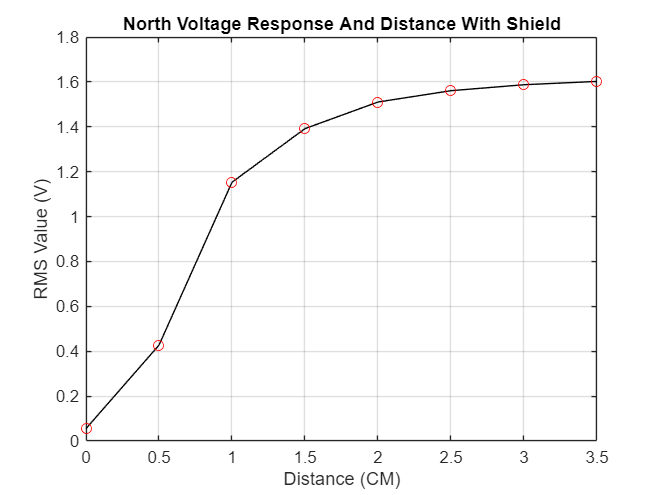


plot(valid_index, valid_data, 'o', 'MarkerEdgeColor', 'r', 'LineStyle', '-', 'Color', 'k');
title('North Voltage Response And Distance With Shield');
xlabel('Distance (CM)');
ylabel('RMS Value (V)');
grid on;

valid_index = linspace(3.5,0,8)

valid_index =     3.5000    3.0000    2.5000    2.0000    1.5000    1.0000    0.5000         0


% valid_indices_list = valid_data(2:2:end);
figure;
disp(valid_data)

    1.6021
    1.5873
    1.5608
    1.5103
    1.3919
    1.1530
    0.4272
    0.0553



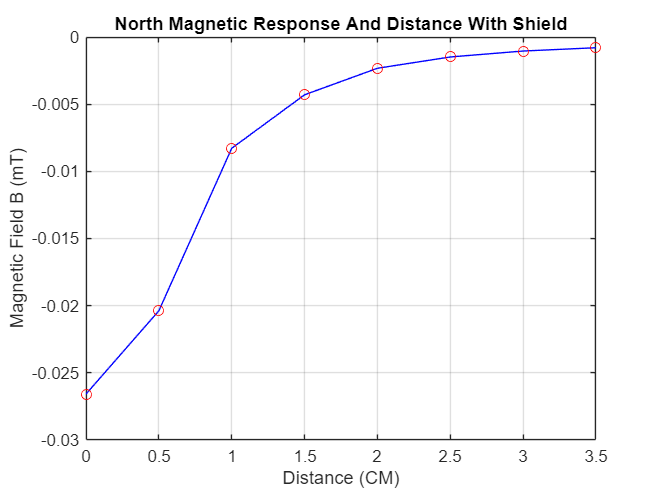


plot(valid_index, B, 'o', 'MarkerEdgeColor', 'r', 'LineStyle', '-', 'Color', 'b');
title('North Magnetic Response And Distance With Shield');
xlabel('Distance (CM)');
ylabel('Magnetic Field B (mT)');
grid on;

%No-Shield-Firstside south
voltage_mearge = [
    1.5981,...
    1.5831,...
    1.5516,...
    1.4899,...
    1.3571,...
    1.0964,...
    0.1639,...
    0.0449,...
    1.6579,...
    1.6762,...
    1.7090,...
    1.7730,...
    1.9337,...
    2.2067,...
    3.2285,...
    3.2477]

voltage_mearge =     1.5981    1.5831    1.5516    1.4899    1.3571    1.0964    0.1639    0.0449    1.6579    1.6762    1.7090    1.7730    1.9337    2.2067    3.2285    3.2477



voltage_mearge_Shield = [
    1.6021,...
    1.5873,...
    1.5608,...
    1.5103,...
    1.3919,...
    1.1530,...
    0.4272,...
    0.0553,...
    1.6557,...
    1.6687,...
    1.6988,...
    1.7534,...
    1.8562,...
    2.1779,...
    2.9351,...
    3.2371,...
    

    ]

voltage_mearge_Shield =     1.6021    1.5873    1.5608    1.5103    1.3919    1.1530    0.4272    0.0553    1.6557    1.6687    1.6988    1.7534    1.8562    2.1779    2.9351    3.2371


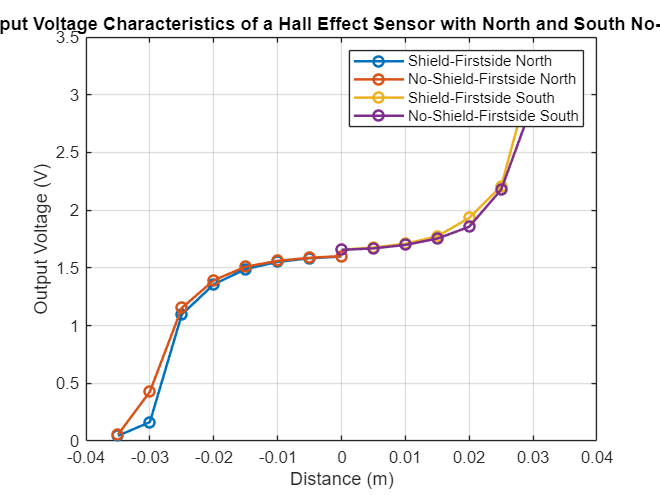

distance = (-0.0:-0.005:-0.035);
voltage_increasing_NoShield = voltage_mearge_Shield(1:8);
voltage_increasing = voltage_mearge(1:8);

distance_g = (0.035:-0.005:0.0);
voltage_decreasing_NoShield = voltage_mearge_Shield(end:-1:9);

voltage_decreasing = voltage_mearge(end:-1:9);
% Plot the output voltage characteristics for both North and South poles
figure;
plot(distance, voltage_increasing, '-o', 'LineWidth', 1.5, 'DisplayName', 'Shield-Firstside North');
hold on;
plot(distance, voltage_increasing_NoShield, '-o', 'LineWidth', 1.5, 'DisplayName', 'No-Shield-Firstside North');

x_pos = max(xlim); % Get the maximum x-axis limit
y_pos = min(ylim); % Get the minimum y-axis limit

plot(distance_g, voltage_decreasing, '-o', 'LineWidth', 1.5, 'DisplayName', 'Shield-Firstside South');
plot(distance_g, voltage_decreasing_NoShield, '-o', 'LineWidth', 1.5, 'DisplayName', 'No-Shield-Firstside South');

hold off;
% xtick(-0.035, -0.030, -0.025, -0.020, -0.015, -0.010, -0.005, 0, 0.005, 0.010, 0.015, 0.020, 0.025, 0.030, 0.035z;
xlabel('Distance (m)');
ylabel('Output Voltage (V)'); % Updated to V as your data is in Volts
title('Output Voltage Characteristics of a Hall Effect Sensor with North and South No-Shield');
legend('show');
grid on;

saveas(gcf, 'Hall_Effect_Sensor_Characteristics_Separated.png');

%Shield-Firstside south

voltage_mearge = [1.5981,...
    1.5831,...
    1.5516,...
    1.4899,...
    1.3571,...
    1.0964,...
    0.1639,...
    0.0449,...
     0.0553,...
    0.4272,...
    1.1530,...
    1.3919,...
    1.5103,...
    1.5608,...
    1.5873,...
    1.6021]

voltage_mearge =     1.5981    1.5831    1.5516    1.4899    1.3571    1.0964    0.1639    0.0449    0.0553    0.4272    1.1530    1.3919    1.5103    1.5608    1.5873    1.6021


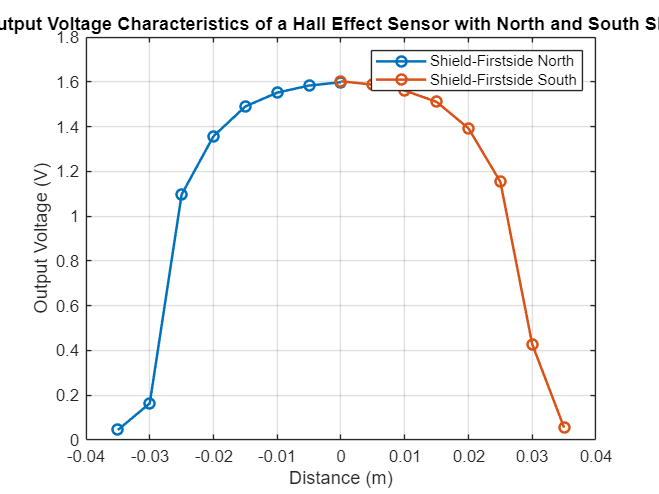

distance = (-0.0:-0.005:-0.035);
voltage_increasing = voltage_mearge(1:8);

distance_g = (0.035:-0.005:0.0);
voltage_decreasing = voltage_mearge(9:end);



% Plot the output voltage characteristics for both North and South poles
figure;
plot(distance, voltage_increasing, '-o', 'LineWidth', 1.5, 'DisplayName', 'Shield-Firstside North');
hold on;
plot(distance_g, voltage_decreasing, '-o', 'LineWidth', 1.5, 'DisplayName', 'Shield-Firstside South');
hold off;

xlabel('Distance (m)');
ylabel('Output Voltage (V)'); % Updated to V as your data is in Volts
title('Output Voltage Characteristics of a Hall Effect Sensor with North and South Shield');
legend('show');
grid on;

saveas(gcf, 'Hall_Effect_Sensor_Characteristics_Separated.png');

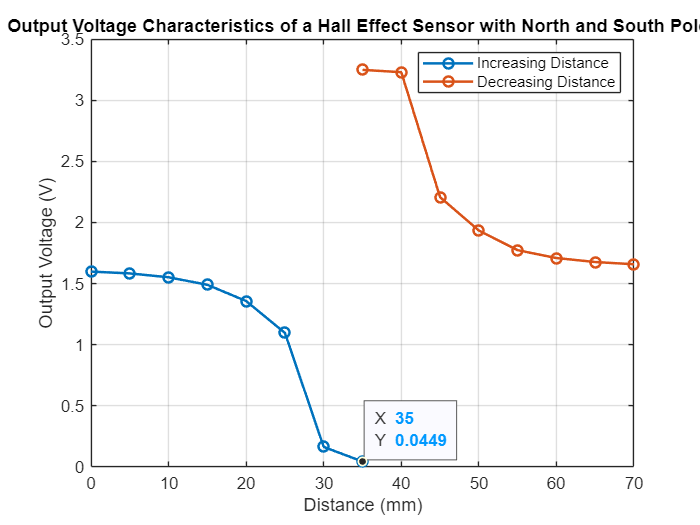

1.5981
    1.5831
    1.5516
    1.4899
    1.3571
    1.0964
    0.1639
    0.0449

 1.6021
    1.5873
    1.5608
    1.5103
    1.3919
    1.1530
    0.4272
    0.0553

%Strain Gauge


mass = linspace(3000,7500,10)
element = out(1);  

data_values = element.simout2.Data;

index = 1:length(data_values);  
if all(isnan(data_values))
    disp('No valid data points available. Check the data source.');
else
    % Filter out NaN or replace them with zero (or another value)
    valid_data = data_values;
    valid_data(isnan(valid_data)) = 0;  % Replace NaN with 0
end
valid_indices = ~isnan(data_values);  
valid_data = data_values(valid_indices);

disp(valid_data)


figure;
plot(mass, valid_data, 'o', 'MarkerEdgeColor', 'b', 'LineStyle', '-', 'Color', 'k');
title('Strain gauge');
xlabel('mass (g)');
ylabel('RMS Value (V)');  
grid on;

% Generate mass values between 3000 and 7500 (10 points)
mass = linspace(3000, 7500, 10);

% Assume 'element' is extracted from a simulation output structure
element = out(1);  

% Extract data from the simulation output
data_values = element.simout2.Data;

% Check if all data values are NaN
if all(isnan(data_values))
    disp('No valid data points available. Check the data source.');
    return; % Exit if no valid data points
else
    % Replace NaN values with zero (or another desired value)
    valid_data = data_values;
    valid_data(isnan(valid_data)) = 0;  % Replace NaN with 0
end

% Alternatively, keep only non-NaN values (if you want to remove NaNs)
valid_indices = ~isnan(data_values);  
valid_data = data_values(valid_indices);

% Fit a linear line to the data using polyfit
p = polyfit(valid_data, mass, 1); % Fit a line with Vrms (valid_data) as x and mass as y

% Extract slope and intercept for inverse equation
slope = p(1);
intercept = p(2);

% Display the inverse equation (mass as a function of Vrms)
fprintf('The equation to find mass from Vrms is: mass = (Vrms - %.2f) / %.2f\n', intercept, slope);

% Plot the original data and fitted line for visual confirmation
figure;
plot(valid_data, mass, 'o', 'MarkerEdgeColor', 'b', 'LineWidth', 1.5, 'MarkerSize', 6); % Original data points
hold on;
plot(valid_data, polyval(p, valid_data), 'r-', 'LineWidth', 1.5); % Fitted line using polyval
title('Mass vs. Vrms with Linear Fit');
xlabel('RMS Value (V)');
ylabel('Mass (g)');
legend('Data points', 'Fitted Line');
grid on;
hold off;

% Generate mass values between 3000 and 7500 (10 points)

mass = (0:250:10000);
element = out(1);  

data_values = element.simout2.Data;

disp(length(data_values))

if all(isnan(data_values))
    disp('No valid data points available. Check the data source.');
    return; % Exit if no valid data points
else
    % Replace NaN values with zero (or another desired value)
    valid_data = data_values;
    valid_data(isnan(valid_data)) = 0;  % Replace NaN with 0
end

% Alternatively, keep only non-NaN values (if you want to remove NaNs)
valid_indices = ~isnan(data_values);  
valid_data = data_values(valid_indices);


     1



% Perform a linear fit
p_linear = polyfit(valid_data, mass, 1); % Linear fit

Error using polyfit (line 49)
The first two inputs must have the same number of elements.


% Perform a quadratic fit (optional step to check non-linear relationships)
p_quadratic = polyfit(valid_data, mass, 2); % Quadratic fit

% Calculate fitted values for each model
mass_fitted_linear = polyval(p_linear, valid_data);
mass_fitted_quadratic = polyval(p_quadratic, valid_data);

% Plot the original data and both fitted lines for visual comparison
figure;
plot(valid_data, mass, 'o', 'MarkerEdgeColor', 'b', 'LineWidth', 1.5, 'MarkerSize', 6); % Original data points
hold on;
plot(valid_data, mass_fitted_linear, 'r-', 'LineWidth', 1.5); % Linear fit
plot(valid_data, mass_fitted_quadratic, 'g--', 'LineWidth', 1.5); % Quadratic fit (dashed line)
title('Mass vs. Vrms with Linear and Quadratic Fits');
xlabel('RMS Value (V)');
ylabel('Mass (g)');
legend('Data points', 'Linear Fit', 'Quadratic Fit');
grid on;
hold off;

% Display the linear equation
fprintf('Linear Fit Equation: mass = (Vrms - %.2f) / %.2f\n', p_linear(2), p_linear(1));

% Display the quadratic equation (if needed)
fprintf('Quadratic Fit Equation: mass = %.2f*Vrms^2 + %.2f*Vrms + %.2f\n', p_quadratic(1), p_quadratic(2), p_quadratic(3));


% Given Vrms value to predict mass (for example, Vrms = 1.5)
Vrms_value = 1.25;

% Calculate mass from the linear fit
calculated_mass_linear = (Vrms_value - p_linear(2)) / p_linear(1);

% Calculate mass from the quadratic fit
calculated_mass_quadratic = polyval(p_quadratic, Vrms_value);

% Display calculated mass values
fprintf('For Vrms = %.2f, the corresponding mass (Linear Fit) is: %.2f g\n', Vrms_value, calculated_mass_linear);

For Vrms = 1.25, the corresponding mass (Linear Fit) is: 0.06 g


fprintf('For Vrms = %.2f, the corresponding mass (Quadratic Fit) is: %.2f g\n', Vrms_value, calculated_mass_quadratic);

For Vrms = 1.25, the corresponding mass (Quadratic Fit) is: 2881.93 g


% Given Vrms value
Vrms_value = 1.5;

% Calculate the corresponding mass using the derived equation
calculated_mass = (Vrms_value - intercept) / slope;

% Display the calculated mass
fprintf('For Vrms = %.2f, the corresponding mass is: %.2f g\n', Vrms_value, calculated_mass);
s

% Generate mass values between 3000 and 7500 (10 points)
mass = (0:250:10000);

% Assume 'element' is extracted from a simulation output structure
element = out(1);  

% Extract data from the simulation output
data_values = element.simout2.Data;

% Check if all data values are NaN
if all(isnan(data_values))
    disp('No valid data points available. Check the data source.');
    return; % Exit if no valid data points
else
    % Replace NaN values with zero (or another desired value)
    valid_data = data_values;
    valid_data(isnan(valid_data)) = 0;  % Replace NaN with 0
end

% Alternatively, keep only non-NaN values (if you want to remove NaNs)
valid_indices = ~isnan(data_values);  
valid_data = data_values(valid_indices);

% Perform a linear fit
p_linear = polyfit(valid_data, mass, 1); % Linear fit

Error using polyfit (line 49)
The first two inputs must have the same number of elements.


% Perform a quadratic fit (optional step to check non-linear relationships)
p_quadratic = polyfit(valid_data, mass, 2); % Quadratic fit

% Calculate fitted values for each model
mass_fitted_linear = polyval(p_linear, valid_data);
mass_fitted_quadratic = polyval(p_quadratic, valid_data);

% Plot the original data and both fitted lines for visual comparison
figure;
plot(valid_data, mass, 'o', 'MarkerEdgeColor', 'b', 'LineWidth', 1.5, 'MarkerSize', 6); % Original data points
hold on;
plot(valid_data, mass_fitted_linear, 'r-', 'LineWidth', 1.5); % Linear fit
plot(valid_data, mass_fitted_quadratic, 'g--', 'LineWidth', 1.5); % Quadratic fit (dashed line)
title('Mass vs. Vrms with Linear and Quadratic Fits');
xlabel('RMS Value (V)');
ylabel('Mass (g)');
legend('Data points', 'Linear Fit', 'Quadratic Fit');
grid on;
hold off;

% Display the linear equation
fprintf('Linear Fit Equation: mass = (Vrms - %.2f) / %.2f\n', p_linear(2), p_linear(1));

% Display the quadratic equation (if needed)
fprintf('Quadratic Fit Equation: mass = %.2f*Vrms^2 + %.2f*Vrms + %.2f\n', p_quadratic(1), p_quadratic(2), p_quadratic(3));

Vrms_value = 1.87253635550655;

% Calculate mass from the linear fit
calculated_mass_linear = (Vrms_value - p_linear(2)) / p_linear(1);

% Calculate mass from the quadratic fit
calculated_mass_quadratic = polyval(p_quadratic, Vrms_value);

% Display calculated mass values
fprintf('For Vrms = %.2f, the corresponding mass (Linear Fit) is: %.2f g\n', Vrms_value, calculated_mass_linear);
fprintf('For Vrms = %.2f, the corresponding mass (Quadratic Fit) is: %.2f g\n', Vrms_value, calculated_mass_quadratic);

